cd(fileparts(matlab.desktop.editor.getActiveFilename));

tbl = readtable("dati/tcurve.txt", NumHeaderLines=3);
tbl.Properties.VariableNames = ["freq", "abs", "phase"];

tbldata = readtable("dati/AD8031_Gain1e3_maxmethod.txt", NumHeaderLines=3);
tbldata.Properties.VariableNames = ["freq", "abs", "s_abs"];

% converto in modulo lineare
tbl.abs = 10.^(tbl.abs/20);
% tbldata.s_abs = 3.8e-4 * ones([size(tbldata.s_abs), 1])

% valori iniziali componenti
R1 = 99.9e3;
C1 = 100e-9;
R2 = 994;
C2 = 47e-9;

t1 = R1*C1;
t2 = R2*C2;

% p(1)=tau1, p(2)=tau2, p(3)=R1, p(4)=C2
% guess iniziale
p0 = [t1, t2, R1, C2];


H = @(p,f) (1j*2*pi*f.*p(1)) ./ ...
           ( (1 + 1j*2*pi*f.*p(1)) .* (1 + 1j*2*pi*f.*p(2)) + 1j*2*pi*f.*p(3).*p(4) );
H_ab = @(p,f) (1j*2*pi*f*p(1)) ./ ( (1 + 1j*2*pi*f/p(2)) .* (1 + 1j*2*pi*f/p(3)));


G = @(p,f) abs(H(p,f))

G = function_handle with value:
    @(p,f)abs(H(p,f))


G_ab = @(p, f) abs(H_ab(p, f))

G_ab = function_handle with value:
    @(p,f)abs(H_ab(p,f))


A = @(p,f) angle(H(p,f))

A = function_handle with value:
    @(p,f)angle(H(p,f))



covabs=1./tbldata.s_abs.^2;

% fit non lineare
[popt,R,J,ccovm, MSE]= nlinfit(tbldata.freq,tbldata.abs,G,p0,"Weights",covabs);

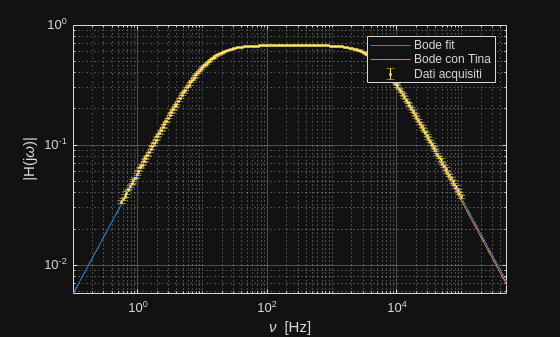




% frequenze logaritmiche da 1 Hz a 1e6 Hz
x = logspace(-1, 6, 10000);

% valutazione della funzione con parametri ottimizzati
y = H( popt,x);

% modulo
figure
loglog(x, abs(y))
hold on
loglog(tbl.freq, tbl.abs)
errorbar(tbldata.freq, tbldata.abs,tbldata.s_abs,".")
hold off
legend("Bode fit", "Bode con Tina","Dati acquisiti");
xlabel('\nu [Hz]')
ylabel('|H(j\omega)|')
xlim([0,5*10^5])
grid on
exportgraphics(gcf,"grafici/BodePassaBanda_Gain_maxmethod.pdf",ContentType="vector");

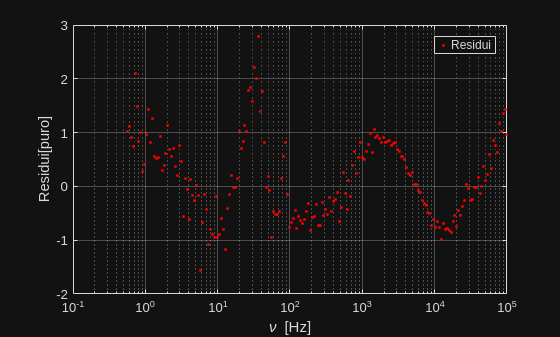



figure
semilogx(tbldata.freq,R,'.r')
legend("Residui");
xlabel('\nu [Hz]')
ylabel('Residui[puro]')
grid on

exportgraphics(gcf,"grafici/BodePassaBanda_Residuals_maxmethod.pdf",ContentType="vector");



fprintf("popt = %.16f\n",popt);

popt = 0.0091824639028596
popt = 0.0000441881139964
popt = 96358.4419826687371824
popt = 0.0000000451434968


fprintf("sigma = %.16f\n",sqrt(diag(ccovm/MSE)));

sigma = 0.0000053676341342
sigma = 0.0000001179978232
sigma = 0.0000000000000000
sigma = 0.0000000000409124


fprintf("Chi2 = %f", MSE);

Chi2 = 0.602894